# Offline analysis (single patient)

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

clearvars; clc;
patients = find_patients('data');
patient = patients{1};
classifiers_fold_root = '../classifiers/'

classifiers_fold_root = '../classifiers/'

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ai6


info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

% Weights for channels and frequencies.
features_weight = load('features_filter.mat').features_filter';

## Process offline data - apply Laplacian filter and compute PSD

PSD_data = cell(size(patient.offline_files));
for f = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


[PSD, EVENT, run_k] = concatenatePSD(PSD_data);

Here we suppose the frequecies of the PSD don't change between the files

info.frequencies = PSD_data{1}.frequencies;

## Create Cue and Trial vectors

[cue_k, trial_k] = label_data(EVENT, length(PSD));

## Apply log and select a grid of frequencies

[PSD, info.frequencies]= extract_frequencies(PSD, info.frequencies, info.selected_frequencies);
PSD = log(PSD); 

## Extract features from PSD based on Fisher score

classes = [info.cue_BF, info.cue_BH];

%features_weight(:, 1:6) = 0; %manually exclude features, if needed

[selected_features , fisher_score_run] = psd2features(PSD, run_k, cue_k, classes, info.num_features, features_weight);
% dataset = extract_features(PSD, selected_features);
% 
% online.features = extractFeatures(online.PSD, selected_freq_chan_index);
%%%% to be equal to the prof
%selected_features={[10 9],[11 9],[5 8]};
dataset = extract_features(PSD, selected_features);

## Reproduce a few steps of psd2features to save the result

mean_fisher_score = mean(fisher_score_run,3);
filtered_mean_Fisher = mean_fisher_score .* features_weight;
features_matrix = feature_map(selected_features,size(mean_fisher_score));

## Visualization of Fisher score

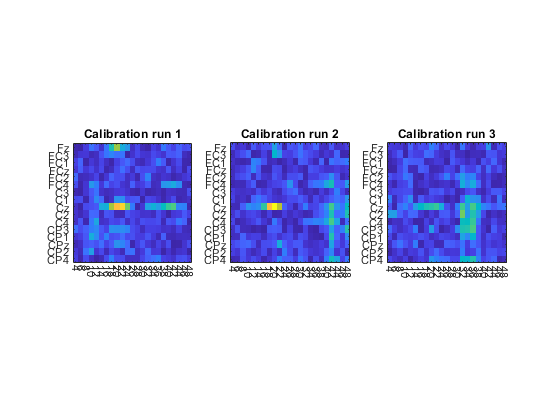

plot_fisher_score(info, info.frequencies, fisher_score_run);

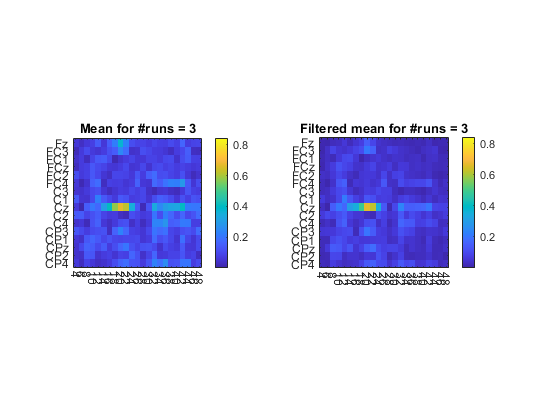

plot_average_fisher(info, info.frequencies, fisher_score_run, features_weight);

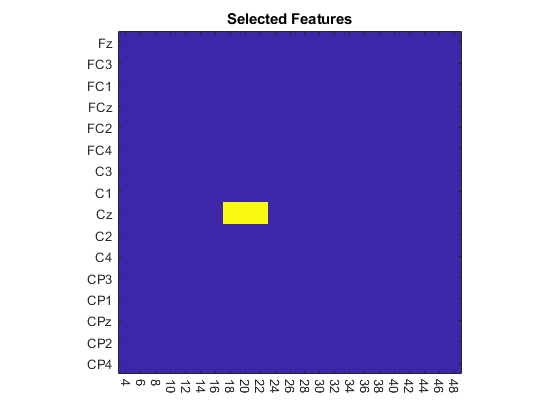

plot_selected_features(info, info.frequencies, fisher_score_run, selected_features);

## Select training samples from data

bh_index = (cue_k== info.cue_BH);
bf_index = (cue_k== info.cue_BF);

train_set = dataset(bh_index | bf_index, :);
true_labels = cue_k(bh_index | bf_index);

## Train classifier

model = train_binary_model(train_set, true_labels);

Model 1 obtained an average test accuracy of: 70.284525.
Model 2 obtained an average test accuracy of: 72.019431.
Model 3 obtained an average test accuracy of: 73.240805.


%model = fitcdiscr(train_set, true_labels, "DiscrimType", "quadratic");

## Results on training set

predicted_labels = predict(model, train_set);
[accuracy, accuracy_per_class] = evaluate_classifier(true_labels, predicted_labels, classes)

accuracy = 74.0736

accuracy_per_class =    62.2814   85.8690


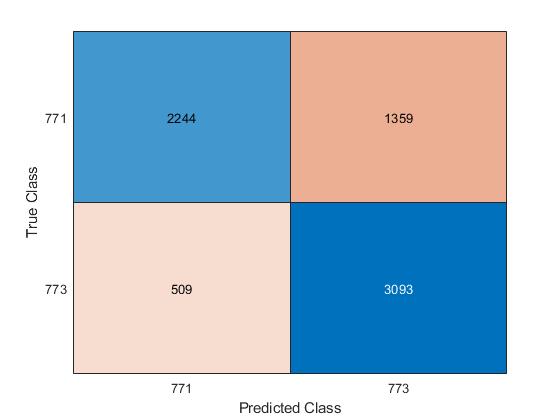

figure;
cm = confusionchart(true_labels, predicted_labels);

confusion_matrix = cm.NormalizedValues;
confusion_matrix_classes = cm.ClassLabels;

## Tuning of Evidence Accumulation parameters

%% Tuning on all offline data

[predicted_labels, post_prob_tuning, ~] = predict(model, dataset);

trial_k_tuning = trial_k;
true_class_tuning = EVENT.TYP(EVENT.TYP==info.cue_BF | EVENT.TYP==info.cue_BH | EVENT.TYP==info.cue_rest);
num_trials_tuning = length(nonzeros(unique(trial_k_tuning)));
true_class_tuning = true_class_tuning(1:num_trials_tuning);

feedbk_ind_tuning = labels_for_event(EVENT, info.feedback_code, length(PSD));
feedbk_starts = EVENT.POS(EVENT.TYP==info.feedback_code);
feedbk_starts_tuning = feedbk_starts(1 : num_trials_tuning);


## Exponential smoothing

framework = @(alpha) exponential_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



exp_param.alpha = params(1);
exp_param.up_threshold = params(2);
exp_param.down_threshold = params(3);

## Dynamic smoothing

free_force = @(ampl,w) (@(x) f_free(x, ampl, w));
bmi_force = @(x) f_bmi(x);

framework = @(alpha, beta, ampl, w) dynamic_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha, beta, free_force(ampl, w), bmi_force);
evaluation = @(x) fitness(x(5), x(6), true_class_tuning, framework(x(1),x(2),x(3),x(4)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 6, [], [], [], [], [0 0 0 0 0.5 0], [1 1 1 0.5 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



dyn_param.alpha = params(1);
dyn_param.beta = params(2);
dyn_param.amp = params(3);
dyn_param.w = params(4);
dyn_param.up_threshold = params(5);
dyn_param.down_threshold = params(6);

## Moving average

framework = @(alpha) mov_avg_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


mov_param.alpha = params(1);
mov_param.up_threshold = params(2);
mov_param.down_threshold = params(3);

# Evidence accumulation performance on offline data

## Classify data

accumulator_ex = exponential_smoothing(post_prob_tuning, feedbk_starts_tuning, exp_param.alpha);
accumulator_dyn = dynamic_smoothing(post_prob_tuning, feedbk_starts_tuning, dyn_param.alpha, ...
    dyn_param.beta, free_force(dyn_param.amp, dyn_param.w), bmi_force);
accumulator_mov = mov_avg_smoothing(post_prob_tuning, feedbk_starts_tuning, mov_param.alpha);

## Accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class_tuning, accumulator_ex, feedbk_ind_tuning, trial_k_tuning)

perf_active_ex = 87.7778

perf_resting_ex = NaN

perf_active_rej_ex = 90.8046

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class_tuning, accumulator_dyn, feedbk_ind_tuning, trial_k_tuning)

perf_active_dyn = 87.7778

perf_resting_dyn = NaN

perf_active_rej_dyn = 90.8046

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_param.up_threshold, mov_param.down_threshold, true_class_tuning, accumulator_mov, feedbk_ind_tuning, trial_k_tuning)

perf_active_mov = 77.7778

perf_resting_mov = NaN

perf_active_rej_mov = 81.3953

## Saving important data

save(strcat(classifiers_fold_root, patient.name, '_classifier'),'model','selected_features', 'exp_param', 'dyn_param', 'mov_param');
save(strcat(classifiers_fold_root, patient.name, '_feature_mask'),'features_matrix');
save(strcat(classifiers_fold_root, patient.name, '_results_train'),'accuracy', 'accuracy_per_class', 'confusion_matrix', 'confusion_matrix_classes');
save(strcat(classifiers_fold_root, patient.name, '_off_tuning_ev_acc'), 'perf_active_ex', 'perf_resting_ex', 'perf_active_rej_ex', ...
    'perf_active_dyn', 'perf_resting_dyn', 'perf_active_rej_dyn', 'perf_active_mov', 'perf_resting_mov', 'perf_active_rej_mov');

Just some functions to plot Fisher score.

function [fit] = fitness(up_threshold, down_threshold,true_class,framework,feedbk_ind,trial_k)
      [c{1:3}]= evaluate_accumulation(up_threshold, down_threshold, true_class, framework, feedbk_ind, trial_k) ;
      c(cellfun(@(c) any(isnan(c)), c)) = [];
      fit = -sum([c{:}]) + std([c{:}])/length(c);
end

function fig = plot_fisher_score(info, psd_frequencies, fisher_score)

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
handles = nan(runs, 1);
fig = figure;

for r = 1:runs
    subplot(1, runs, r);
    imagesc(fisher_score(:, :, r)');
    axis square;
    set(gca, 'XTick', 1:freq);
    set(gca, 'XTickLabel', psd_frequencies);
    set(gca, 'YTick', 1:chan);
    set(gca, 'YTickLabel', info.channel_labels);
    xtickangle(-90);
    title(['Calibration run ' num2str(r)]);
    caxis([m, M]);
    handles(r) = gca;
end

end

function fig = plot_average_fisher(info, psd_frequencies, fisher_score, feature_weights)

mean_fisher = mean(fisher_score, 3);
filt_fisher = mean_fisher .* feature_weights;

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

subplot(1,2,1);
imagesc(mean_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Mean for #runs = ' num2str(runs)]);

subplot(1,2,2);
imagesc(filt_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Filtered mean for #runs = ' num2str(runs)]);

end

function fig = plot_selected_features(info, psd_frequencies, fisher_score, selected_features)

features_mask = zeros(size(fisher_score(:,:,1)));

for k = 1 : length(selected_features)
    feature_index = selected_features{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
title('Selected Features');

end